# Object Detection Using Faster R-CNN Deep Learning

Este exemplo mostra como treinar um detector de objetos Faster R-CNN (regiões com redes neurais convolucionais).

A aprendizagem profunda é uma técnica poderosa de aprendizado de máquina que você pode usar para treinar detectores de objetos robustos. Existem várias técnicas de aprendizado profundo para detecção de objetos, incluindo Faster R-CNN e you only look once (YOLO) v2. Este exemplo treina um detector de veículos Faster R-CNN usando a função trainFasterRCNNObjectDetector. Para mais informações, consulte Detecção de Objetos.

## Baixar Detector Pré-Treinado

Baixe um detector pré-treinado para evitar ter que esperar o treinamento ser concluído. Se você deseja treinar o detector, defina a variável doTraining como verdadeira.

doTraining = true;
if ~doTraining && ~exist('fasterRCNNResNet50EndToEndVehicleExample.mat','file')
    disp('Downloading pretrained detector (118 MB)...');
    pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/fasterRCNNResNet50EndToEndVehicleExample.mat';
    websave('fasterRCNNResNet50EndToEndVehicleExample.mat',pretrainedURL);
end

## Load Data Set 

Este exemplo utiliza um pequeno conjunto de dados rotulados que contém 295 imagens. Muitas dessas imagens são provenientes dos conjuntos de dados Caltech Cars 1999 e 2001, criados por Pietro Perona e usados com permissão. Cada imagem contém uma ou duas instâncias rotuladas de um veículo. Um conjunto de dados pequeno é útil para explorar o procedimento de treinamento Faster R-CNN, mas na prática, mais imagens rotuladas são necessárias para treinar um detector robusto. Descompacte as imagens de veículos e carregue os dados de verdade absoluta do veículo.

data = load('tabelaCruz.mat');
vehicleDataset = data.T

vehicleDataset = 100×2 table
      imageFilename              cruz        
    _________________    ____________________

    "arquivo_670.jpg"    {[  195 760 115 77]}
    "arquivo_670.jpg"    {[1006 440 100 229]}
    "arquivo_671.jpg"    {[  132 777 117 89]}
    "arquivo_671.jpg"    {[1009 435 112 248]}
    "arquivo_672.jpg"    {[   58 799 125 93]}
    "arquivo_672.jpg"    {[1015 433 128 263]}
    "arquivo_673.jpg"    {[1010 432 140 285]}
    "arquivo_674.jpg"    {[ 990 426 165 310]}
    "arquivo_675.jpg"    {[ 958 424 178 335]}
    "arquivo_676.jpg"    {[ 904 428 210 352]}
    "arquivo_677.jpg"    {[ 831 431 237 337]}
    "arquivo_679.jpg"    {[ 734 439 262 398]}
    "arquivo_681.jpg"    {[ 595 436 300 425]}
    "arquivo_682.jpg"    {[ 468 443 313 444]}
    "arquivo_683.jpg"    {[ 314 452 351 459]}
    "arquivo_684.jpg"    {[ 156 465 350 458]}


Os dados do veículo são armazenados em uma tabela de duas colunas, onde a primeira coluna contém os caminhos dos arquivos de imagem e a segunda coluna contém as caixas delimitadoras dos veículos.

Divida o conjunto de dados em conjuntos de treinamento, validação e teste. Selecione 60% dos dados para treinamento, 10% para validação e o restante para testar o detector treinado.

rng(0)
shuffledIndices = randperm(height(vehicleDataset));
idx = floor(0.6 * height(vehicleDataset));

trainingIdx = 1:idx;
trainingDataTbl = vehicleDataset(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = vehicleDataset(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = vehicleDataset(shuffledIndices(testIdx),:);

Use `imageDatastore` e `boxLabelDatastore` para criar datastores para carregar os dados de imagem e rótulos durante o treinamento e avaliação..

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,'cruz'));

imdsValidation = imageDatastore(validationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(validationDataTbl(:,'cruz'));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,'cruz'));

Combine os datastores de imagem e rótulos de caixa.

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

Exiba uma das imagens de treinamento e os rótulos de caixa.

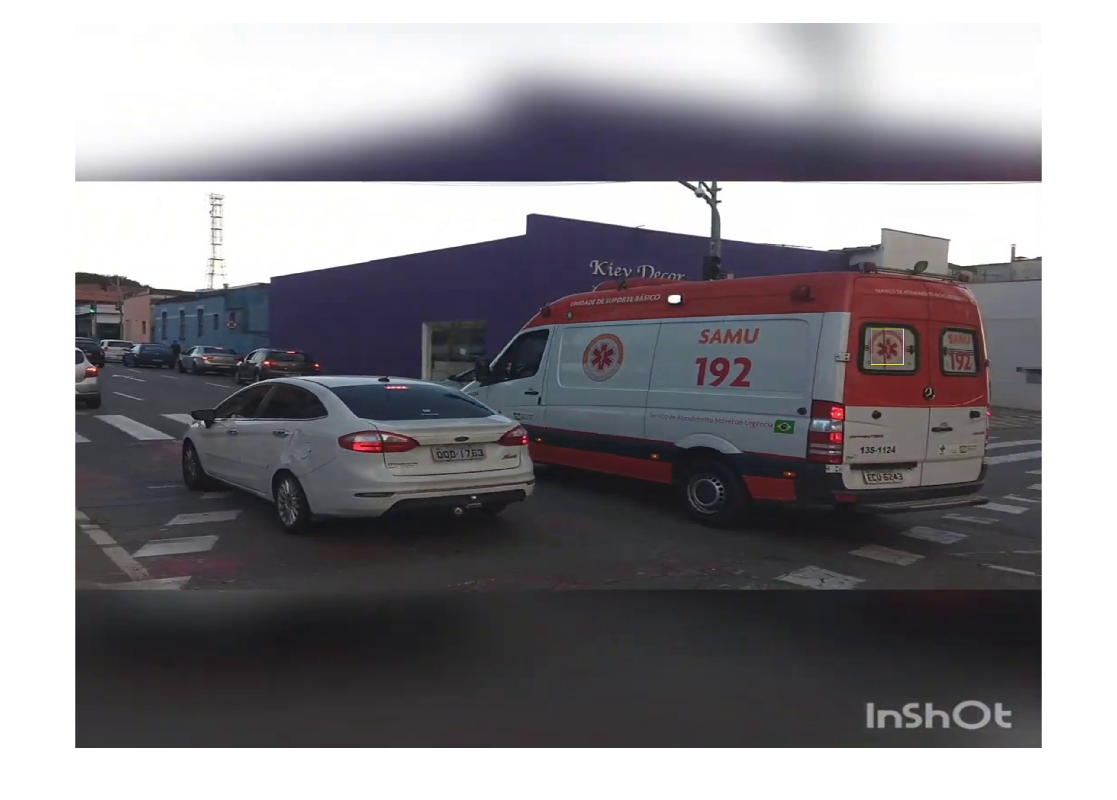

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

## Create Faster R-CNN Detection Network

Uma rede de detecção de objetos Faster R-CNN é composta por uma rede de extração de características seguida por duas sub-redes. A rede de extração de características é tipicamente uma CNN pré-treinada, como ResNet-50 ou Inception v3. A primeira sub-rede que segue a rede de extração de características é uma rede de proposição de regiões (RPN, do inglês "region proposal network") treinada para gerar propostas de objetos - áreas na imagem onde objetos provavelmente existem. A segunda sub-rede é treinada para prever a classe real de cada proposta de objeto.

A rede de extração de características é tipicamente uma CNN pré-treinada (para detalhes, consulte Redes Neurais Profundas Pré-treinadas). Este exemplo usa ResNet-50 para extração de características. Você também pode usar outras redes pré-treinadas, como MobileNet v2 ou ResNet-18, dependendo dos requisitos da sua aplicação.

Use `fasterRCNNLayers` para criar automaticamente uma rede Faster R-CNN dada uma rede de extração de características pré-treinada. `fasterRCNNLayers` requer que você especifique várias entradas que parametrizam uma rede Faster R-CNN:

- Tamanho de entrada da rede

- Caixas âncora

- Rede de extração de características

Primeiro, especifique o tamanho de entrada da rede. Ao escolher o tamanho de entrada da rede, considere o tamanho mínimo necessário para executar a própria rede, o tamanho das imagens de treinamento e o custo computacional incorrido ao processar dados no tamanho selecionado. Quando viável, escolha um tamanho de entrada da rede que seja próximo ao tamanho da imagem de treinamento e maior do que o tamanho de entrada necessário para a rede. Para reduzir o custo computacional de executar o exemplo, especifique um tamanho de entrada da rede de [224 224 3], que é o tamanho mínimo necessário para executar a rede.

inputSize = [608 608 3];

Observe que as imagens de treinamento usadas neste exemplo são maiores do que 224 por 224 e variam de tamanho, então você deve redimensionar as imagens em uma etapa de pré-processamento antes do treinamento.

Em seguida, use `estimateAnchorBoxes` para estimar caixas âncora com base no tamanho dos objetos nos dados de treinamento. Para considerar o redimensionamento das imagens antes do treinamento, redimensione os dados de treinamento para estimar as caixas âncora. Use `transform` para pré-processar os dados de treinamento, em seguida, defina o número de caixas âncora e estime as caixas âncora.

preprocessedTrainingData = transform(trainingData, @(data)preprocessData(data,inputSize));
numAnchors = 9;
anchorBoxes = estimateAnchorBoxes(preprocessedTrainingData,numAnchors)

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


anchorBoxes =    139    79
    28    25
   232   128
   105   106
    57    34
   139    51
    49    28
    36    25
    53    48


Para obter mais informações sobre a escolha de caixas âncora, consulte "Estimate Anchor Boxes from Training Data" (Estimar Caixas Âncora a partir de Dados de Treinamento) no Computer Vision Toolbox™ e "Anchor Box Basics" (Fundamentos de Caixas Âncora).

Agora, use `resnet50` para carregar um modelo ResNet-50 pré-treinado. 

featureExtractionNetwork = resnet50;

Selecione 'activation_40_relu' como a camada de extração de características. Esta camada de extração de características produz mapas de características que são reduzidos por um fator de 16. Esta quantidade de redução é um bom equilíbrio entre resolução espacial e a força das características extraídas, já que características extraídas mais profundamente na rede codificam características de imagem mais fortes ao custo da resolução espacial. Escolher a camada de extração de características ideal requer análise empírica. Você pode usar o método `analyzeNetwork` para encontrar os nomes de outras potenciais camadas de extração de características dentro de uma rede.

featureLayer = 'activation_40_relu';

Defina o número de classes a detectar.

numClasses = width(vehicleDataset)-1;

Crie a rede de detecção de objetos Faster R-CNN.

lgraph = fasterRCNNLayers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

Você pode visualizar a rede usando `analyzeNetwork` ou o Deep Network Designer do Deep Learning Toolbox™. Se mais controle sobre a arquitetura da rede Faster R-CNN for necessário, use o Deep Network Designer para projetar manualmente a rede de detecção Faster R-CNN. Para mais informações, consulte "R-CNN, Fast R-CNN, and Faster R-CNN Basics" (Noções Básicas de R-CNN, Fast R-CNN e Faster R-CNN).

## Train Faster R-CNN

Use `trainingOptions` para especificar as opções de treinamento da rede. Defina 'ValidationData' para os dados de validação pré-processados. Defina 'CheckpointPath' para um local temporário. Isso permite salvar detectores parcialmente treinados durante o processo de treinamento. Se o treinamento for interrompido, como por uma queda de energia ou falha do sistema, você pode retomar o treinamento a partir do ponto de verificação salvo.

options = trainingOptions('sgdm',...
    'MaxEpochs',10,...
    'MiniBatchSize',1,...
    'InitialLearnRate',1e-3,...
    'CheckpointPath',tempdir,...
    'ValidationData',validationData,...
     'ExecutionEnvironment','gpu');

Use `trainFasterRCNNObjectDetector` para treinar o detector de objetos Faster R-CNN se `doTraining` for verdadeiro. Caso contrário, carregue a rede pré-treinada.

if doTraining
    % Train the Faster R-CNN detector.
    % * Adjust NegativeOverlapRange and PositiveOverlapRange to ensure
    %   that training samples tightly overlap with ground truth.
    [detector, info] = trainFasterRCNNObjectDetector(trainingData,lgraph,options, ...
        'NegativeOverlapRange',[0 0.3], ...
        'PositiveOverlapRange',[0.6 1]);
else
    % Load pretrained detector for the example.
    pretrained = load('fasterRCNNResNet50EndToEndVehicleExample.mat');
    detector = pretrained.detector;
end

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* cruz

Initializing input data normalization.
|==========================================================================================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  RPN Mini-batch  |  RPN Mini-batch  |  Validation  |  Validation  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |     Accuracy     |       RMSE       |     Loss     |   Accuracy   |     RMSE     |      Rate       |
|==========================================================================================================================================================================================|
|       1 |           1 |       00:02:38 |      

Este exemplo foi verificado em uma GPU Nvidia™ Titan X com 12 GB de memória. O treinamento da rede levou aproximadamente 20 minutos. O tempo de treinamento varia dependendo do hardware que você está usando.

Como uma verificação rápida, execute o detector em uma imagem de teste. Certifique-se de redimensionar a imagem para o mesmo tamanho das imagens de treinamento.

%I = imread(testDataTbl.imageFilename{3});
%I = imresize(I,inputSize(1:2));
I = imread("arquivo_8065.jpg");
[bboxes,scores,labels] = detect(detector,I);

%[bboxes,scores] = detect(detector,I);

Exiba os resultados.

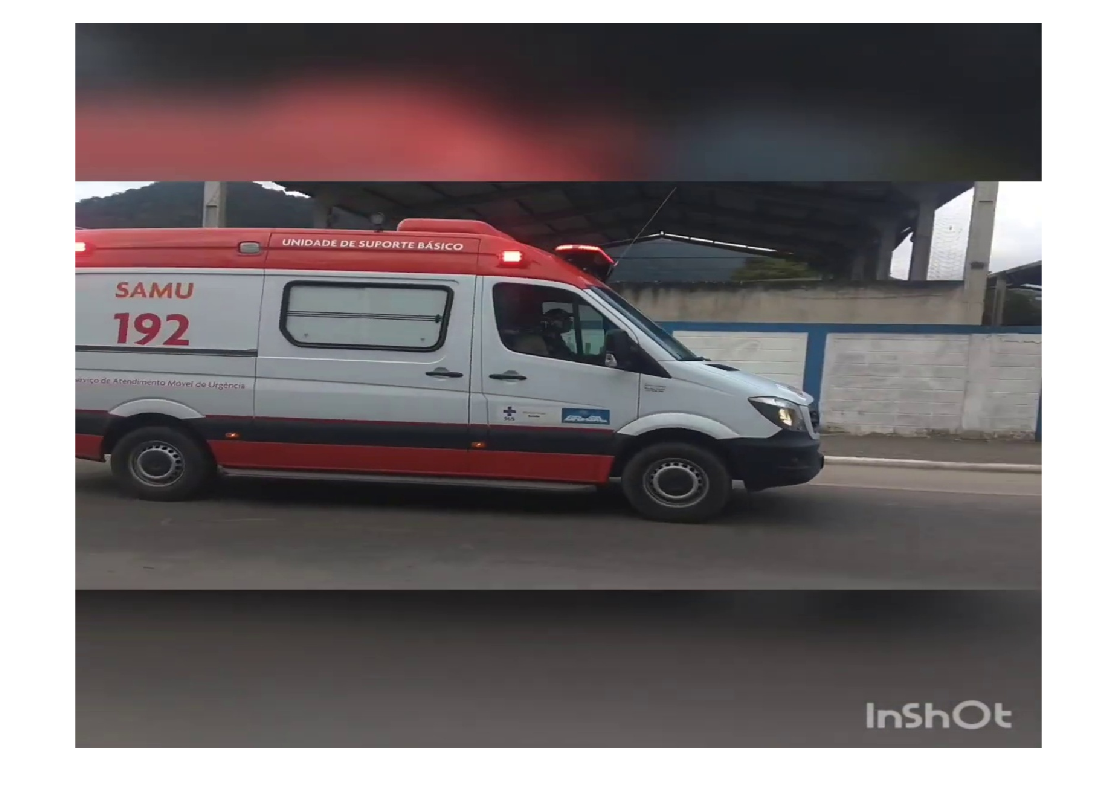

I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
figure
imshow(I)

## Evaluate Detector Using Test Set

Avalie o detector de objetos treinado em um grande conjunto de imagens para medir o desempenho. O Computer Vision Toolbox™ fornece uma função de avaliação de detector de objetos (evaluateObjectDetection) para medir métricas comuns como precisão média e taxa de erro médio logarítmico. Para este exemplo, use a métrica de precisão média para avaliar o desempenho. A precisão média fornece um único número que incorpora a capacidade do detector de fazer classificações corretas (precisão) e a capacidade do detector de encontrar todos os objetos relevantes (recall).

Rode o detector em todas as imagens de teste.

detectionResults = detect(detector,testData,'MinibatchSize',4);   

Avalie o detector de objetos usando a métrica de precisão média.

classID = 1;
metrics = evaluateObjectDetection(detectionResults,testData);
precision = metrics.ClassMetrics.Precision{classID};
recall = metrics.ClassMetrics.Recall{classID};

A curva precisão-recall (PR) destaca quão preciso um detector é em diferentes níveis de recall. A precisão ideal é 1 em todos os níveis de recall. O uso de mais dados pode ajudar a melhorar a precisão média, mas pode exigir mais tempo de treinamento. Plote a curva PR.

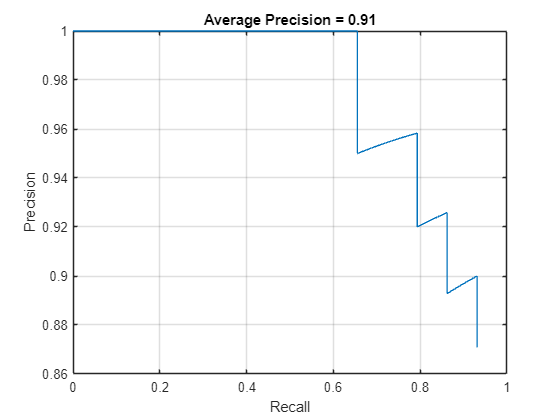

figure
plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f', metrics.ClassMetrics.mAP(classID)))

## References

[1] Ren, S., K. He, R. Gershick, and J. Sun. "Faster R-CNN: Towards Real-Time Object Detection with Region Proposal Networks." *IEEE Transactions of Pattern Analysis and Machine Intelligence*. Vol. 39, Issue 6, June 2017, pp. 1137-1149.

[2] Girshick, R., J. Donahue, T. Darrell, and J. Malik. "Rich Feature Hierarchies for Accurate Object Detection and Semantic Segmentation." *Proceedings of the 2014 IEEE Conference on Computer Vision and Pattern Recognition*. Columbus, OH, June 2014, pp. 580-587.

[3] Girshick, R. "Fast R-CNN." *Proceedings of the 2015 IEEE International Conference on Computer Vision*. Santiago, Chile, Dec. 2015, pp. 1440-1448.

[4] Zitnick, C. L., and P. Dollar. "Edge Boxes: Locating Object Proposals from Edges." *European Conference on Computer Vision*. Zurich, Switzerland, Sept. 2014, pp. 391-405.

[5] Uijlings, J. R. R., K. E. A. van de Sande, T. Gevers, and A. W. M. Smeulders. "Selective Search for Object Recognition." *International Journal of Computer Vision*. Vol. 104, Number 2, Sept. 2013, pp. 154-171.

*Copyright 2016-2022 The MathWorks, Inc.*